# **ACM 11 Homework 5 Part 2/2**

# ** (Spring 2024)**

## **Due Friday, June 7th, 11:59pm Pacific Time, by upload to Canvas.**

This assignment is composed of two parts. This second part is worth $60$ points. You should read the problem set-up in this file and follow the instructions to write and test your code.

## Introduction to Regularization

As mentioned in lecture, fitting functions to data is often an **ill-posed **problem, which means that there may be multiple solutions to the problem. This non-uniqueness may lead our numerical algorithm to find solutions will non-desirable behavior, such as having polynomial interpolants that are highly oscillatory, and hence do not match the target function where the data came from.

As an example of an ill-posed problem, let us consider finding a solution of the linear system $Ax = b$ where $A \in \mathbb{R}^{n \times d}$ and $b\in\mathbb{R}^n$ with fewer observations/constraints $n$ than  the number of unknowns $d$. In this case, if we seek a least-squares solution by minimizing the squared $\ell^2$-norm  

$\min_{x \in \mathbb{R}^d} \ |\!| Ax - b |\!|_2^2$,

then this optimization problem will have more than one solution, in general. To make data fitting problems like the one above well-posed, it is common to add a regularization term to the optimization problem that encourages us to recover a solution that best fits the data, while obeying another constraint or condition.

In this portion of the homework, we will explore two types of regularization, which are based on adding either the $\ell^1$ or $\ell^2$ norm to the least-squares objective to arrive at the following optimization problems:


$$\ell^1 \ : \ \min_{x \in \mathbb{R}^d} \ |\!| Ax - b |\!|^2_2 + \lambda \cdot  |\!| x |\!|_1$$



$$\ell^2 \ : \ \min_{x \in \mathbb{R}^d} \ |\!| Ax - b |\!|^2_2 + \lambda \cdot  |\!| x |\!|^2_2$$


where $\lambda$ is a regularization parameter that controls the strength of the regularization parameter. This parameter allows us to trade-off how closely we fit the data with the penalty we impose on the solution. Recall that the $\ell^1$ and $\ell^2$ norms are given by: $\|x\|_1 = \sum_{j=1}^d x_j$ and $\|x\|_2^2 = \sum_{j=1}^d x_j^2$.

The $\ell^1$ and $\ell^2$ problems are also known as `lasso` and `ridge` regression, respectively, in the statistics community. If you are interested in learning more about these methods, we highly encourage you to take **ACM 158** in Winter 2026. 

## Problem 3: Theoretical Investigation of the regularized least-squares problem (20 points)

We will first see how we can derive closed form formulas for the solution vector in the $\ell_2$ regularized optimization problem. To save you the trouble, there is **no** closed form solution for the $\ell^1$ regularization problem (Why might this be the case?).

In class we showed that one can find the explicit solution $x^*$ to the $\ell_2$ regularized optimization problem above as follows:


$$x^* = (A^{\top}A + \lambda I)^{-1}A^{\top}b$$


**Problem 3a (10 points): **In this problem, we will extend the regularized solution to weighted least-squares problems. Given n data samples ${\left\lbrace \left(z_{i,} ,y_i \right)\right\rbrace }_{i=1}^n$ with $z_i \in \mathbb{R}^d$, and $y_i \in \mathbb{R}$, consider the following weighted least-squares problem for the coefficients $\beta \in \mathbb{R}^d$ in a linear regression model:


$$\min_{\beta \in \mathbb{R}^d} \sum_{i=1}^n w_i (z_i^T \beta - y_i)^2 + \lambda \sum_{j=1}^d \beta_j^2$$


where $w_i \in \mathbb{R}$ are non-negative weights. 

Write down the solution to this optimization problem for $\beta \in \mathbb{R}^d$. Hint: Write the optimization problem using the standard form above for the regularized least-squares objective. Take the derivative of the objective function with respect to the vector $\beta$, and set it equal to $0$. It may be useful to use the following identities given $a$ is a vector.


$$\frac{\partial a^{\top}Ba}{\partial a} = (B + B^{\top})a$$



$$\frac{\partial a^{\top}x}{\partial a} = \frac{\partial x^{\top}a}{\partial a} = x$$


**Problem 3b (5 points): **Comment on the computational complexity of solving the resulting linear system in terms of $d$ and $n$. Which parts of the cost dominate for problems with large datasets, i.e., $n \geq d$, and problems with high-dimensional models, i.e., $d > n$? Hint: Do not forget the cost of assembling the vectors and matrices appearing in the objective.

fprintf(['The computational complexity of solving this linear system in terms of d and n is \n' ...
    'O(n*d^2) (because the n x d matrix times d columns) to assemble the matrix and O(d^3) to solve \n' ...
    'the matrix. With very large datasets, the cost of assembling the matrix dominates \n' ...
    'while the cost of solving the matrix dominates for high-dimensional models.'])

The computational complexity of solving this linear system in terms of d and n is 
O(n*d^2) (because the n x d matrix times d columns) to assemble the matrix and O(d^3) to solve 
the matrix. With very large datasets, the cost of assembling the matrix dominates 
while the cost of solving the matrix dominates for high-dimensional models.

**Problem 3c (5 points): **What is the necessary condition for a solution $\beta$ to exist when $\lambda = 0$? How does this change for $\lambda > 0$?

fprintf(['The necessary condition for a solution for beta to exist when lambda = 0 \n' ...
    'is that w has to be positive definite for A^TwA to be invertible (and positive definite, \n' ...
    'assuming A is full-rank), and since w is a diagonal matrix, it is positive \n' ...
    'definite only when all of the weights are positive. This changes for lambda > 0 \n' ...
    'because this does not require A^TwA to be positive definite, so w does not have to be \n' ...
    'positive definite, so not all of the weights have to be positive. Therefore, there is always \n' ...
    'a solution when lambda > 0 because I (the identity matrix) is positive definite.'])

The necessary condition for a solution for beta to exist when lambda = 0 
is that w has to be positive definite for A^TwA to be invertible (and positive definite, 
assuming A is full-rank), and since w is a diagonal matrix, it is positive 
definite only when all of the weights are positive. This changes for lambda > 0 
because this does not require A^TwA to be positive definite, so w does not have to be 
positive definite, so not all of the weights have to be positive. Therefore, there is always 
a solution when lambda > 0 because I (the identity matrix) is positive definite.

## Problem 4: Numerical Investigation of regularization methods (20 points)

We will now numerically investigate the behavior of two forms of regularization for solving the under-determined linear system $Ax = b$ where $A \in \mathbb{R}^{4 \times 10}$ and $b \in \mathbb{R}^4$.

The code below will setup a random matrix $A$ and a right hand side vector $b = Ax^\dagger$ for some true solution $x^\dagger \in \mathbb{R}^{10}$. Out goal will be to evaluate the recovery of the true solution given only $A,b$ through $\ell_1$ and $\ell_2$ regularization methods. 

clear; close all

% For reproducibility of results
rng(5,'twister') 

% Generate A matrix
dim  = 10;
nobs = 4;
A = randn(nobs, dim);

% Define true sparse vector
xtrue = [10*rand(3,1);zeros(dim-3,1)];

% Generate corresponding right-hand side vector b
b = A*xtrue;

% Recover the minimum-norm solution, i.e. MATLAB's default regularization
x_no_reg = A\b;
fprintf('No reg error: %f\n', norm(xtrue - x_no_reg))

No reg error: 7.539081


**Problem 4a (5 points):** Write code to evaluate the solution to the $\ell_1$ and $\ell_2$ regularization problems for solving the linear system defined above with the set value of $\lambda=0.1$. For the $\ell_1$ problem, use the function LASSO to recover $x$. This function takes as input $A$, $b$ and the regularization parameter $\lambda$. See the documentation for how to specify $\lambda$. For the $\ell_2$ problem, write the solution using the closed form expression for the solution of the un-weighted regularized least-squares problem.

% set regularization parameter
lambda = 0.1;

% Compute the l1 regularized solution
[l1, info] = lasso(A, b, 'Lambda',lambda);

% Compute the l2 regularized solution
l2 = (A'*A + lambda*eye(dim))\A'*b;

**Problem 4b (5 points): **What do you notice about the solution vectors $x$ recovered by the regularized $\ell_1$ and $\ell_2$ problems?

fprintf(['The solution vector for the l1 problem is mostly 0, while the solution \n ' ...
    'vector for l2 is fully populated with values that range from -3 to 6.'])

The solution vector for the l1 problem is mostly 0, while the solution 
 vector for l2 is fully populated with values that range from -3 to 6.

**Problem 4c (5 points): **Evaluate the error between the recovered solutions of the $\ell_1$ and $\ell_2$ regularization problems with the true solution vector $x^\dagger$. Evaluate the error using the $\ell_2$ norm. Comment on how the error compares to the solution computed without explicit regularization using the backslash operation above.

% Code for the computation of the l2 error
l1_error = norm(l1 - xtrue - info.Intercept)

l1_error = 0.0637

l2_errr = norm(l2-xtrue)

l2_errr = 6.4518

**Problem 4d) (5 points): **Evaluate the $\ell^2$ regularized solution for the minimizer of the weighted least-squares problem with the weights vector: $w = (1,1,1,100)$. How does introducing a weight change the $\ell^2$ error of the recovered solution?

% Code for solving the weighted least-squares problem
w = diag([1, 1, 1, 10]);

l2_weight = ((A'*w*A)+lambda*eye(dim))\(A'*w*b);
l2_wieght_errr = norm(l2_weight-xtrue)

l2_wieght_errr = 6.4512

## Problem 5: Application to the Auto Dataseet (20 points)

We will now apply regularization methods to the auto dataset considered in Part 1 of this assignment.

**Problem 5a (2 points): **Please load the ''Auto.csv" data set into MATLAB. In this part, we will use 7 variables (cylinders, displacement, horsepower, weight, acceleration, year and origin) to build a linear predictor for MPG. After loading the data, assemble the 7 predictors into a data matrix $X$ and set the output as a column vector $Y$.

data = readtable('Auto.csv');

% Code to read and format data

X = table2array(table(data.cylinders, data.displacement, data.horsepower, ...
                data.weight, data.acceleration, data.year, data.origin));
Y = table2array(table(data.mpg));

**Problem 5b (3 points): **Split your data into a training and test set. For $n_{\textrm{train}} =300$, use the first $n_{\textrm{train}}$ entries of $y$ and rows of $X$ for training, and save the remaining entries/rows for testing the fitted model. 

% Code to split data into training and testing
n_train = 300;
y_train = Y(1:300, :);
x_train = X(1:300, :);
x_test = X((n_train + 1):end, 1);
y_test = Y((n_train+1):end, 1);

**Problem 5c (10 points) **Try different values of parameters $\lambda$ for fitting a linear model to the training data using $\ell^1$ regularization. Hint: You may find it insightful to plot the values of each model coefficient versus lambda. That is, have $\lambda$ on the x-axis, the coefficient's value on the y-axis and include one line for each coefficient. Which coefficients are most important and least important as you change $\lambda$? How does this relate to your experimental results in Part 1?

Based on the graph, it seems that coefficients for cylinders, origin, and year are the most important as lambda is changed. This relates to the experimental results in part 1 because the highest correlation coefficients for MPG are with these variables. 

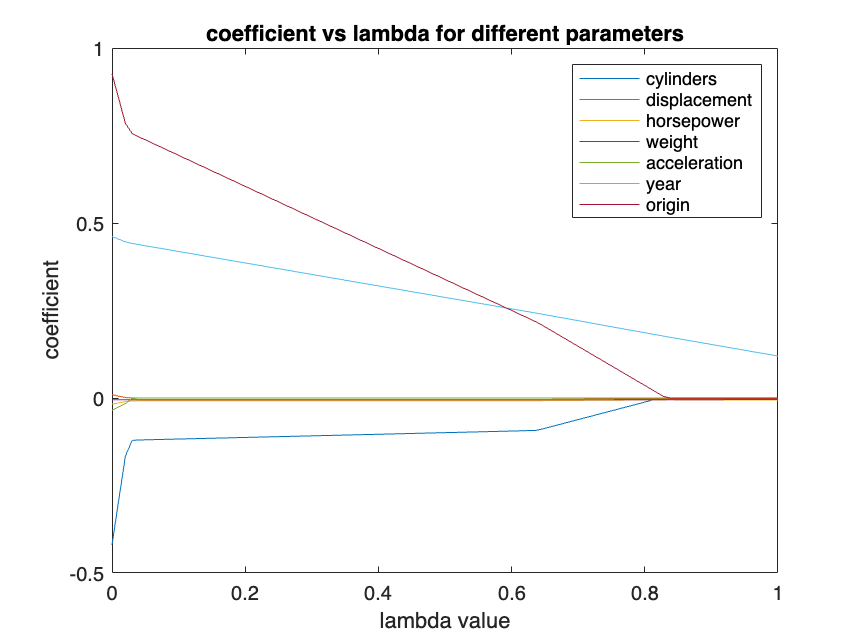

% Code to plot recovered solution vs. lambda
num_lambdas = 100;
lambda_list = linspace(0, 1, num_lambdas);
labels = ["cylinders", "displacement", "horsepower", "weight", "acceleration","year","origin"];
coeff_list = zeros(num_lambdas, 7);

for i= 1:num_lambdas
    lambda = lambda_list(i);
    [l1, ~] = lasso(x_train, y_train, 'Lambda',lambda);
    coeff_list(i, :) = l1';
end
figure;
for j = 1:7
    plot(lambda_list, coeff_list(:, j));
    hold on;
end
legend(labels);
xlabel('lambda value');
ylabel('coefficient');
title('coefficient vs lambda for different parameters');

**Problem 5d (5 points): **Evaluate the mean-squared prediction error of the models on both the training and test sets as a function of lambda for both $\ell^1$ and $\ell^2$ regularization. It is often recommend to evaluate the prediction error using multiple splits of the data. You can use the code below, which uses 5 splits of the data into training and test sets. For each fold, train the model with the training dataset (train_X, train_y) and evaluate the error using (test_X, test_y). The final prediction averages the errors across the 5 splits. Hint: Do not forget to include the intercept when evaluating the error of the $\ell^1$ regularized solution.

Was there an optimal vale of $\lambda$, and how does this value differ if you use the training or test sets to determine the optimal parameter?

The optimal value of lambda according to the training was the first value of lambda, while there was not an optimal value according to the test sets (the minimum for for l1 was 14, and the minimum for l2 was 44).

% Code for evaluating the training and test error
lambda_vals = logspace(-4,2,50);

% define data splits
Nfolds = 5;
rng(1);
c = cvpartition(size(X,1),"KFold",Nfolds);

% Store training/testing error
train_error_l1 = zeros(Nfolds,length(lambda_vals));
test_error_l1  = zeros(Nfolds,length(lambda_vals));
train_error_l2 = zeros(Nfolds,length(lambda_vals));
test_error_l2  = zeros(Nfolds,length(lambda_vals));

for j=1:Nfolds

    % Extract training samples
    train_y = Y(c.training(j));
    train_X = X(c.training(j),:);
    [~, dim] = size(train_X);
    
    % Extract testing samples
    test_y = Y(c.test(j));
    test_X = X(c.test(j),:);

    for i = 1:length(lambda_vals)
        
        % Compute l_1 and l_2 estimates using (train_X, train_y)
        [l1, info] = lasso(train_X, train_y, 'Lambda',lambda_vals(i));
        l1_int = [info.Intercept; l1];

        %l2 = (train_X'*train_X + lambda_vals(i)*eye(dim))\(train_X'*train_y);
        l2 = ridge(train_y, train_X, lambda_vals(i), 0);
        intercept = l2(1);
        l2 = l2(2:end);
        % Compute training and testing errors using (test_X, test_y)
        train_pred_l1 = [ones(length(train_X), 1), train_X] * l1_int;
        test_pred_l1 = [ones(length(test_X), 1), test_X] * l1_int;
    
        train_error_l1(j, i) = mean((train_y - train_pred_l1).^2);
        test_error_l1(j, i) = mean((test_y - test_pred_l1).^2);

        train_pred_l2 = train_X * l2 + intercept;
        test_pred_l2 = test_X*l2 + intercept;
    
        train_error_l2(j, i) = mean((train_y - train_pred_l2).^2);
        test_error_l2(j, i) = mean((test_y - test_pred_l2).^2);
        
    end
end

% Average errors and find index for the optimal value of lambda
[min_l1_train,ind_l1_train] = min(squeeze(mean(train_error_l1,1)))

min_l1_train = 10.7752

ind_l1_train = 1

[min_l1_test,ind_l1_test]   = min(squeeze(mean(test_error_l1,1)))

min_l1_test = 11.5299

ind_l1_test = 14

[min_l2_train,ind_l2_train] = min(squeeze(mean(train_error_l2,1)))

min_l2_train = 10.7752

ind_l2_train = 1

[min_l2_test,ind_l2_test]   = min(squeeze(mean(test_error_l2,1)))

min_l2_test = 11.5063

ind_l2_test = 36

lambda_vals(14)

ans = 0.0039

lambda_vals(1)

ans = 1.0000e-04

lambda_vals(36)

ans = 1.9307

In the text box below explain which regularization method performs best for this problem in terms of minimum mean squared error and why you believe this is the case.

fprintf(['l1 regularization performs best for this problem because it has \n' ...
    'the lowest MSE. This may be because the predicted values for l1 method are \n' ...
    'very similar to one another (they are all about 22.443), but the values from \n' ...
    'the l2 method are more varied. Also, l1 only considers the properties that actually\n' ...
    'are important for the output variable (it only has a few non-zero coefficients). On\n' ...
    'the other hand, l2 tries to make coefficients even for the variables that do not matter.'])

l1 regularization performs best for this problem because it has 
the lowest MSE. This may be because the predicted values for l1 method are 
very similar to one another (they are all about 22.443), but the values from 
the l2 method are more varied. Also, l1 only considers the properties that actually
are important for the output variable (it only has a few non-zero coefficients). On
the other hand, l2 tries to make coefficients even for the variables that do not matter.

### **Problem 6: Time Spent (0 points)**

How many hours did you spend on both parts of this homework in total? Please round to the nearest half hour: 

hours = 4;